This scrip is to use to find the best-fitted time step between simulation and experiment.

pls change the **simMSDType** variable, and input the **expMSDData** manually(C:\Users\zhouquan\OneDrive\research\scrips\processed_data).

V1spline

We try to use spline instead of customed function(a*t^b+c) to get a more resonable timestep.

pnValue='p';
epDistance=47;
expMSDName=[pnValue,num2str(epDistance)];
expMSDType=[pnValue,num2str(epDistance),' 0.05DifferenceDiscard'];
if epDistance==47
    aSlantWell=2;
elseif epDistance==77
    aSlantWell=1.27;
elseif epDistance==179
    aSlantWell=0.63;
end
k2=0.35;
%simMSDType=['twoStage V1=1000(r-',num2str(aSlantWell),'); V2=',num2str(k2),'r^2'];
simMSDType=['twoStage V1=1000(r-',num2str(aSlantWell),'); V2=',num2str(k2),'(re-rp)^2'];
load(['C:\Users\zhouquan\OneDrive\research\polychrom simulation\newProcessedData\mixed data ',expMSDType,'.mat']);
MSDmultiplier=1e-18*(340*epDistance/100)^2;

spFunction=spline(average_time_list,MSD_average);
%figure
%plot(average_time_list,MSD_average);

t_exp=t_mixMSD(1,:);
MSD_exp=t_mixMSD(2,:);
b_scale_min=1;
b_scale_delta=1;
%b_scale=[1,2,5,10,100,200,500,1000,2e3,5e3,1e4,2e4,5e4,1e5];
if 1000<average_time_list(end)/max(t_exp)
    b_scale=b_scale_min:b_scale_delta:1000;
else
    b_scale=b_scale_min:b_scale_delta:average_time_list(end)/max(t_exp);
end
residual_list=[];
residual_min=1e100;
for b=b_scale
    residual=0;
    for t=1:length(t_exp)
        residual=residual+(MSDmultiplier*(ppval(spFunction,t_exp(t)*b))-MSD_exp(t)*1e-18)^2;
    end
    %select the min residual b
    if residual<=residual_min
        b_min=b;
        residual_min=residual;
    end
    residual_list=[residual_list;residual];
end

residual figure

figure
subplot(1,2,1)
plot(b_scale,residual_list,'LineWidth',2)
title({'residual between expMSD and simMSD';simMSDType;''},"FontSize",15)
set(gca,'xscale','log')
set(gca,'yscale','log')
xlabel('timestep multiplier b/10^{-15}')
ylabel('sim-exp residual/m^4')

show the exp MSD and sim MSD

first calculate sim MSD

%b_min=4e2;
sim_list=[];
%b_min=100000;
t=1:max(t_exp)/1000:max(t_exp);
sim_list=MSDmultiplier*ppval(spFunction,t*b_min);


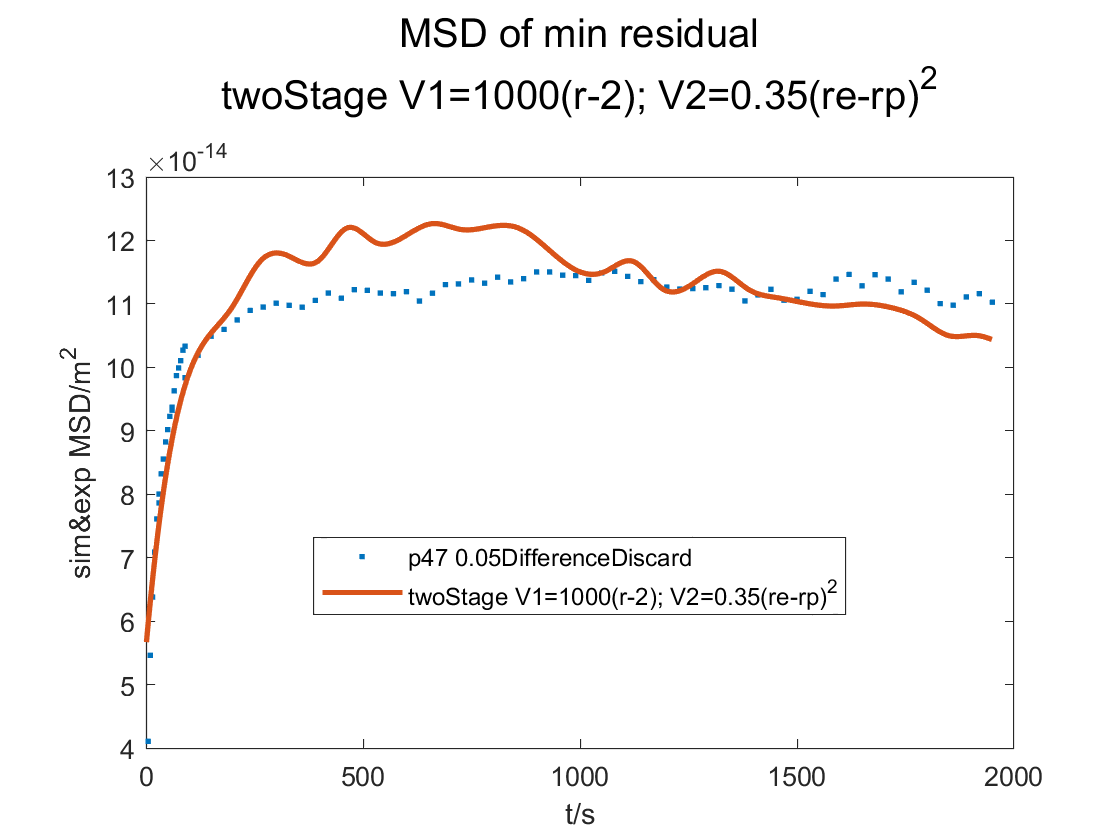

subplot(1,2,2);
plot(t_exp,MSD_exp*1e-18,'.','DisplayName',expMSDType)
hold on
plot(1:max(t_exp)/1000:max(t_exp),sim_list,'DisplayName',simMSDType,'LineWidth',2)
plot(average_time_list*b_min,MSDmultiplier*MSD_average,"LineWidth",2)
plot(average_time_list/b_min,2.56e-14*MSD_average,"LineWidth",2,"DisplayName",'origin MSD')
title({'MSD of min residual';simMSDType;''},"FontSize",15)
xlabel('t/s')
ylabel('sim&exp MSD/m^2')
set(gca,'yscale','log')
legend('Location',"best")